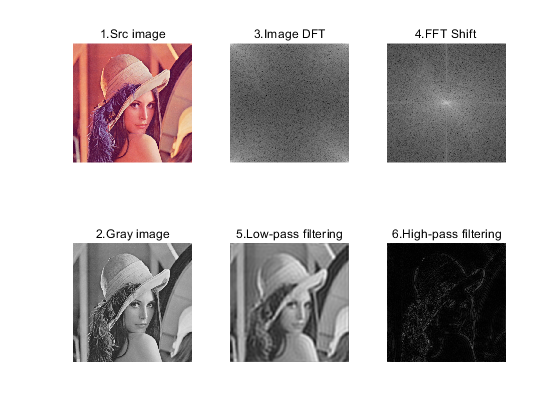

clear; close all;

Src = imread('lena_opcv.jpg');
Src_Gray = rgb2gray(Src);

Src_fft = fft2(Src_Gray);
Src_fftshift = fftshift(Src_fft);

[Rows,Cols] = size( Src_fftshift );
n = 4;
Cutoff_freq = 30;
m = fix( Rows/2 );
n = fix( Cols/2 );
Filter_lowpass = zeros(Rows,Cols);
Filter_highpass = zeros(Rows,Cols);

for i = 1 : Rows
    for j = 1 : Cols
        d_eucl = sqrt((i - m)^2 + (j - n)^2);
        Filter_lowpass(i,j) = 1/(1 + (d_eucl/Cutoff_freq)^(2*n));
        Filter_highpass(i,j) = 1/(1 + (Cutoff_freq/d_eucl)^(2*n));
    end
end

H_low = Filter_lowpass .* Src_fftshift;
H_high = Filter_highpass .* Src_fftshift;

Dst_lowpass = ifft2(H_low);
Dst_lowpass = uint8(abs(Dst_lowpass));

Dst_highpass = ifft2(H_high);
Dst_highpass = uint8(abs(Dst_highpass));

%% show image
subplot(2,3,1);
imshow(Src);
title('1.Src image');

subplot(2,3,4);
imshow(Src_Gray);
title('2.Gray image');

subplot(2,3,2);
imshow(log(abs(Src_fft) + 1),[]);
title('3.Image DFT');

subplot(2,3,3);
imshow(log(abs(Src_fftshift) + 1),[]);
title('4.FFT Shift ');

subplot(2,3,5);
imshow(Dst_lowpass);
title('5.Low-pass filtering');

subplot(2,3,6);
imshow(Dst_highpass);
title('6.High-pass filtering');